# `Ex010 - ARPES Eb(kx,kz) Branched Data Processing at ADRESS`

This example shows how to perform common operations on ARPES data using the functions of the MATools and PESTools toolkit.

For a more in-depth explanation of potential in- and output of those functions, consult the UserGuide.

**(1) Loading in the data**

close all; clear all; 
help load_adress_data;

  dataStr = load_adress_data(FileName, PathName)
    This function loads in the HDF5 data files of ARPES data from 
    the ADRESS beamline at the SLS. The output is a MATLAB
    data-structure that yields all the data and information. This function 
    should be used to load in a single ADRESS data-file that is unprocessed
    or has been previously processed using PESTools. Last updated in
    October 2022, and includes electrostatic tilt extraction.
 
    REQ. FUNCTIONS:
    -   [data, axes, note]  = ReaderHDF5(fname);
 
    IN:
    -   FileName:           char of the input .h5 or .mat file-name.
    -   PathName:           char of the input .h5 or .mat directory path.
 
    OUT:
    dataStr - MATLAB data structure containing all fields below;
 	 .(FileName):       string of the current filename of the data file.
 	 .(H5file):         string of the raw .H5 filename of the data file.
 	 .(TimeStamp):      time-stamp of when the file was created.
 	 .(Type):         

path_data   = 'D:\OneDrive\PCC_MS_Project\00_SLS_Software\ARPEScape\ARPEScape-v8.1.0\PESTools_PCC\Examples\Example_Data\';
arpes_raw = load_adress_data('010_ARPES_kxkz.h5', path_data);

Loading ADRESS data...


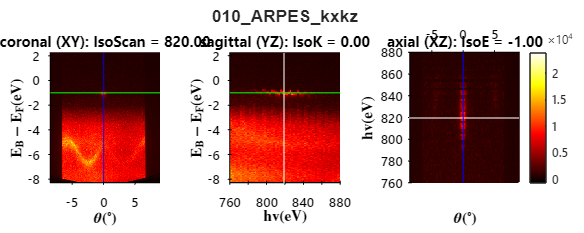

arpes_dat = delete_scans(arpes_raw, {[2:2:2e3]});   % deleting every even numbered scan, so only the odd-numbered ARPES scans remain
arpes_ref = delete_scans(arpes_raw, {[1:2:2e3]});   % deleting every odd numbered scan, so only the even-numbered XPS scans remain
% -- Viewing the ARPES data
slice_args   = {820, -1.00, 0.00};
view_arpes_data(arpes_dat,slice_args);

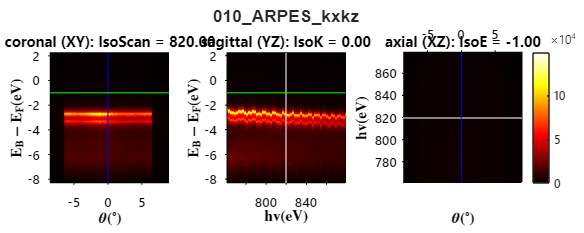

view_arpes_data(arpes_ref,slice_args);

**(2) - Binding energy alignment to the reference data**

help align_energy;

  [dataStr, dataStr_ref] = align_energy(dataStr, align_args, dataStr_ref, plot_result)
    - #1 - FIRST STEP IN PROCESSING ARPES DATA
    This is a function that will align the 'dataStr' ARPES data-structure 
    to the Fermi-level, a peak, or reference VB or CB state. The energy
    alignment is done using various approaches that the user can select from,
    either using the 'dataStr' or a reference 'dataStr_ref' data file. 
        (1) 'align2ref'  : aligns to some peak or edge reference using MATools AlignEF() function.
        (2) 'fit2ef'    : fits directly to the FDD edge of a reference. 
        (3) 'fit2peak'  : fits directly to some peak feature.
        (4) 'gsv1s'     : global shift via one scan aligned to some peak / edge reference using MATools AlignEF() function.
 
    IN:
    -   dataStr:            data structure of the ARPES data.
    -   align_args:         {1×7} cell of {Type,Scans,eWin, dEWin, dESmooth, feat}.
                                Type: 

% - AUTOMATIC COARSE ALIGNMENT TO THE CORE-LEVEL REFERENCE
alignType   = "align2ref";
scan_indxs	= [];
eWin        = [-2.4, -3];
dEWin       = 1.00;
dESmooth    = [];
feat        = 'peak';
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat};
[arpes_dat, arpes_ref]  = align_energy(arpes_dat, align_args, arpes_ref);

- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment
- EF alignment


- Re-mapping
- Re-mapping


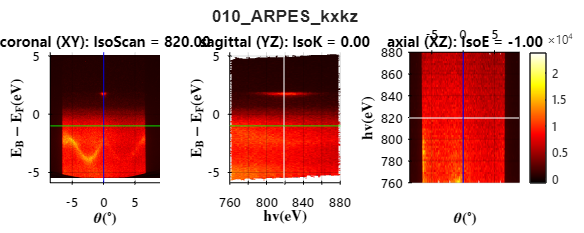

view_arpes_data(arpes_dat,slice_args);

- Re-mapping
- Re-mapping


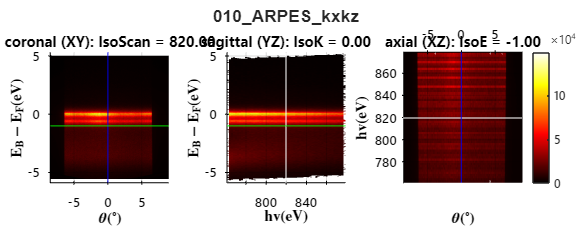

view_arpes_data(arpes_ref,slice_args);

% - FINE ALIGNMENT TO KNOW REFERENCE
alignType   = "global shift via scan"; 
scan_indxs	= 30;
eWin        = 2.00;
dEWin       = 1.00;
dESmooth    = [];
feat        = 'edge';
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat};
arpes_dat  = align_energy(arpes_dat, align_args);

- EF alignment


- Re-mapping
- Re-mapping


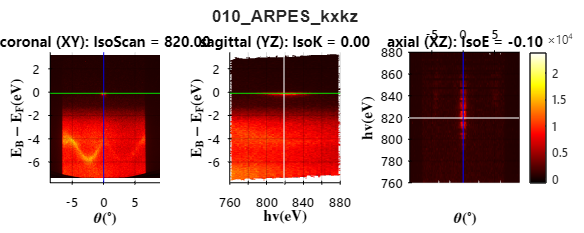

slice_args   = {820, -0.10, 0.00};
view_arpes_data(arpes_dat,slice_args);

**(1.3) - Background subtraction and intensity normalisation**

help bgrd_subtr_data;

  dataStr = bgrd_subtr_data(dataStr, bsub_args, plot_result)
    - #2 - SECOND STEP IN PROCESSING ARPES DATA
    This is a function that will background subtract / normalise the ARPES data using several
    different approaches over a given window.
 
    REQ. FUNCTIONS:
    -   [xField, yField, zField, dField] = find_data_fields(dataStr);
    -   DataC=SetContrast(Data,minFrac,maxFrac [,gamma]);
 
    IN:
    -   dataStr:        data structure of the ARPES data.
    -   bsub_args:      {1×5} cell of {bgrdType,bgrdWin,bgrdScale,bgrdSmooth,normType}.
                                bgrdType:       "AngleInt"
                                                "AngleInt-clip"
                                                "AngleInt-mean"
                                                "AngleInt-pctile"
                                                "AngleInt-mean-moving"
                                                "AngleInt-pctile-moving"
                               

- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating
- Angle integrating


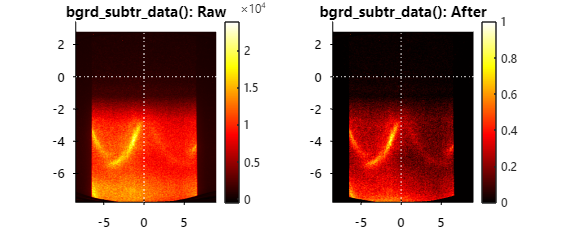

bgrdType    = "AngleInt-clip";
bgrdWin     = [];
bgrdScale   = 0.75;
bgrdSmooth  = 25;
normType    = "max-each";
bgrd_args   = {bgrdType, bgrdWin, bgrdScale, bgrdSmooth, normType}; 
arpes_dat = bgrd_subtr_data(arpes_dat, bgrd_args, 1); 

- Re-mapping
- Re-mapping


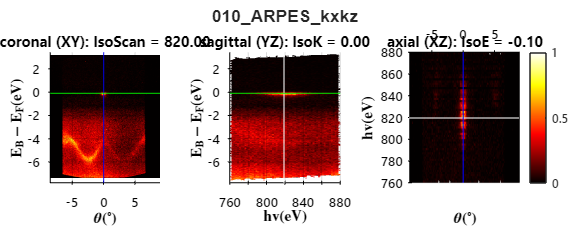

view_arpes_data(arpes_dat,slice_args);

**(1.4) - Wave-vector conversions**

help convert_to_k;

  dataStr = convert_to_k(dataStr, kconv_args, plot_result)
    - #3 - THIRD STEP IN PROCESSING ARPES DATA
    This is a function that will convert the angles thtA into kx and the
    scan parameters into either ky (for tltM) or kz (for hv).  Last updated in
    October 2022, and includes input for new X-ray incidence angle.
 
    REQ. FUNCTIONS:
    -   [xField, yField, zField, dField] = find_data_fields(dataStr);
    -   surfNormX = SurfNormX(hv, eB_ref, kx_ref, thtM, thtA_ref) calculates the surface normal angle in the MP.
    -   Kxx = Kxx(HV, Eb, thtM, ThtA, surfNormX) calculates k// in the MP.
    -   Kyy = Kyy(HV, Eb, thtM, TltM, surfNormX) calculates k// in the MP.
    -   Kzz = Kzz(HV, Eb, thtM, ThtA, TltM, v000, surfNormX) calculates kz along the surface normal.
 
    IN:
    -   dataStr:        data structure of the ARPES data.
    -   kconv_args:     {1×5} cell of {eB_ref, kx_ref, thtA_ref, v000, incAlpha}.
                                eB_ref:    	single,

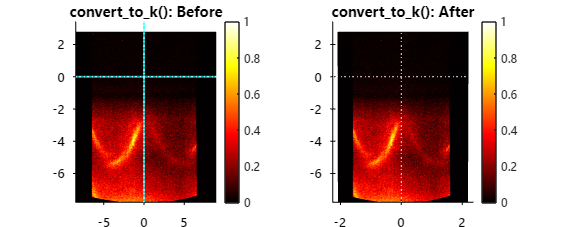

eB_ref      = 0;
kx_ref      = 0;
thtA_ref    = 0;
v000        = 12.57;
inc_alpha   = 9;
kconv_args  = {eB_ref, kx_ref, thtA_ref, v000, inc_alpha}; 
arpes_dat = convert_to_k(arpes_dat, kconv_args, 1);

- Re-mapping
- Re-mapping


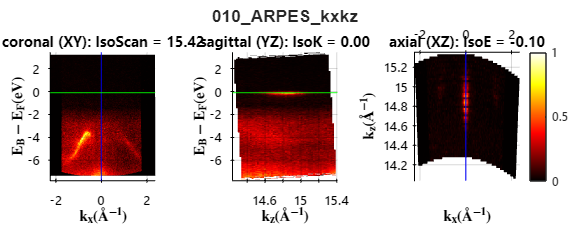

arpes_dat.kx = arpes_dat.kx + 0.000;
view_arpes_data(arpes_dat,slice_args);

**(1.5) - Final data structure**

arpes_dat

arpes_dat = struct with fields:
       FileName: '010_ARPES_kxkz'
         H5file: '010_ARPES_kxkz.h5'
      TimeStamp: "05-Oct-2021 17:33:02"
           Type: "Eb(kx,kz)"
          index: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 … ] (1×122 double)
           meta: [1×1 struct]
             hv: [760 762 764 766 768 770 772 774 776 778 780 782 784 786 788 790 792 794 796 798 800 802 804 806 808 810 812 814 816 818 820 822 824 826 828 830 832 834 836 838 840 842 844 846 848 850 852 854 856 858 860 862 864 866 … ] (1×61 double)
           tltM: 0.9100
           tltE: 0
           thtM: 1.0300
           Temp: 10.3000
       raw_data: [688×391×61 double]
        raw_tht: [-8.5000 -8.4551 -8.4103 -8.3654 -8.3205 -8.2756 -8.2308 -8.1859 -8.1410 -8.0962 -8.0513 -8.0064 -7.9615 -7.9167 -7.8718 -7.8269 -7.7821 -7.7372 -7

## (4A) Extracting an *iso-scan* slice

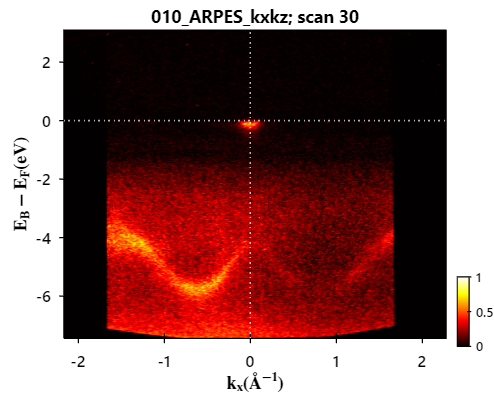

scanStr_01 = struct with fields:
    isoscan_args: {[30]}
          xField: "kx"
        FileName: '010_ARPES_kxkz'
            Type: "Eb(kx,kz)"
         IsoType: "Scan"
          IsoVal: 30
           XScan: [688×391 double]
           YScan: [688×391 double]
           DScan: [688×391 double]


nFrame         = 30;            % Scan number to be cut
isoscan_args   = {nFrame};      % Scan number to isolate
plot_result    = 1;             % Show a plot of the data that is extracted. if 1, it will make the plot, if 0 it won't.
[scanStr_01, ~] = extract_isoScan(arpes_dat, isoscan_args, plot_result); scanStr_01

## (4B) Extracting *iso-cut* profiles

- Data cut formation


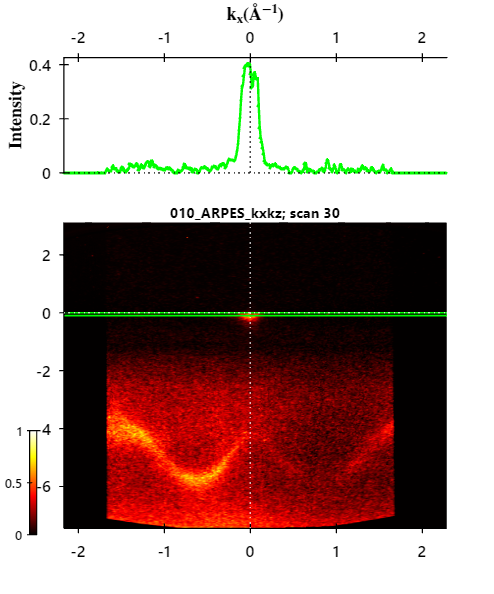

cutStr_01 = struct with fields:
    isocut_args: {[30]  ["MDC"]  [-0.1000 0]}
         xField: "kx"
       FileName: '010_ARPES_kxkz'
           Type: "Eb(kx,kz)"
        IsoType: "MDC"
         IsoVal: -0.0500
         IsoWin: 0.0500
         IsoNum: 1
           XCut: [-2.1638 -2.1524 -2.1410 -2.1297 -2.1183 -2.1069 -2.0956 -2.0842 -2.0728 -2.0615 -2.0501 -2.0387 -2.0273 -2.0160 -2.0046 -1.9932 -1.9818 -1.9705 -1.9591 -1.9477 -1.9363 -1.9249 -1.9135 -1.9022 -1.8908 -1.8794 -1.8680 -1.8566 -1.8452 … ]
           DCut: [6.8922e-04 0 0 0 0 3.1329e-04 0 0 0 0 0.0013 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 8.9081e-04 0 0 0 0 0 0 2.8149e-04 0.0020 0 3.9099e-05 6.0385e-05 0.0015 0 0 0 0.0023 0.0074 0.0160 0.0125 0.0089 0.0083 0.0088 0.0226 0.0279 0.0153 0.0154 … ]


nFrame          = 30;                   % Scan number to be cut
% -- EXTRACT MDC CUT
cutType         = "MDC";                % Type of cut to make. Either "MDC" (horizontal) or "EDC" (vertical)
cutWin          = [-0.1, 0.0];          % Integration window of the cut to be made.
isocut_args     = {nFrame, cutType, cutWin};
[cutStr_01, ~]  = extract_isoCut(arpes_dat, isocut_args); cutStr_01

- Data cut formation


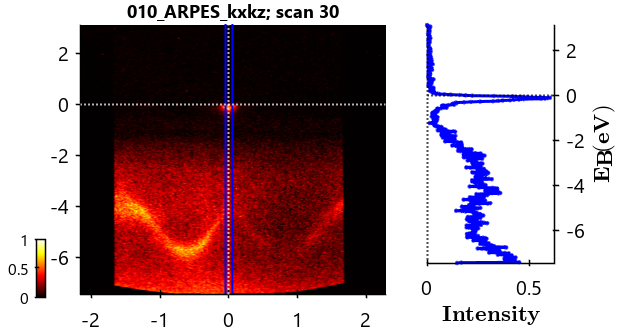

cutStr_02 = struct with fields:
    isocut_args: {[30]  ["EDC"]  [-0.0500 0.0500]}
         xField: "kx"
       FileName: '010_ARPES_kxkz'
           Type: "Eb(kx,kz)"
        IsoType: "EDC"
         IsoVal: 0
         IsoWin: 0.0500
         IsoNum: 1
           XCut: [688×1 double]
           DCut: [688×1 double]


% -- EXTRACT EDC CUT
cutType         = "EDC";                % Type of cut to make. Either "MDC" (horizontal) or "EDC" (vertical)
cutWin          = [-0.05, 0.05];        % Integration window of the cut to be made.
isocut_args     = {nFrame, cutType, cutWin};
[cutStr_02, ~]   = extract_isoCut(arpes_dat, isocut_args); cutStr_02

- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation
- Data cut formation


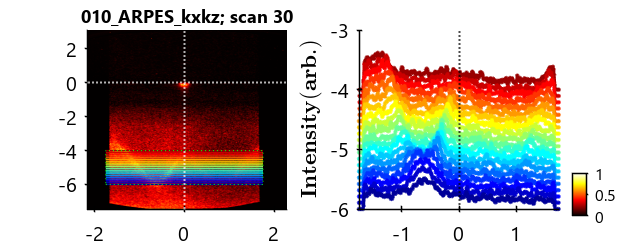

cutStr_03 = struct with fields:
    isocut_args: {[30]  ["MDC"]  [0.0500]  [-1.7500 1.7500]  [-6 -4]  [20]}
         xField: "kx"
       FileName: '010_ARPES_kxkz'
           Type: "Eb(kx,kz)"
        IsoType: "MDC"
         IsoVal: [-6 -5.8947 -5.7895 -5.6842 -5.5789 -5.4737 -5.3684 -5.2632 -5.1579 -5.0526 -4.9474 -4.8421 -4.7368 -4.6316 -4.5263 -4.4211 -4.3158 -4.2105 -4.1053 -4]
         IsoWin: [-0.0500 0.0500]
         IsoNum: 20
           XCut: {1×20 cell}
           DCut: {1×20 cell}


% -- EXTRACT SERIES OF MDC CUTS
isocutType          = "MDC";            % Type of line profile to extract. "EDC" (vertical) or "MDC" (horizontal)
isocutWin           = 0.05;             % single, constant valueof the integration window.
isocutXLims         = [-1.75, 1.75];    % 1x2 vector which gives the x-axis limits of the train [minX, maxX]
isocutYLims         = [-6, -4];         % 1x2 vector which gives the y-axis limits of the train [minY, maxY]
isocutN             = 20;               % single, constant value that determines the total number of line profiles to extract
isocut_args         = {nFrame, isocutType, isocutWin, isocutXLims, isocutYLims, isocutN};
plot_result         = 1;                % Show a plot of the data that is extracted. if 1, it will make the plot, if 0 it won't.
[cutStr_03, ~]      = extract_isoCut_series(arpes_dat, isocut_args, plot_result); cutStr_03

## (4C) Extracting *iso-slice* surfaces

- Data slice formation
- Re-mapping


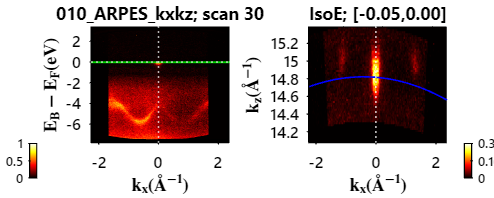

sliceStr_01 = struct with fields:
    isoslice_args: {[30]  ["IsoE"]  [-0.0500 0]  [1]}
         ScanAxis: [760 762 764 766 768 770 772 774 776 778 780 782 784 786 788 790 792 794 796 798 800 802 804 806 808 810 812 814 816 818 820 822 824 826 828 830 832 834 836 838 840 842 844 846 848 850 852 854 856 858 860 862 864 866 868 870 872 … ]
           xField: "kx"
         FileName: '010_ARPES_kxkz'
             Type: "Eb(kx,kz)"
          IsoType: "IsoE"
           IsoWin: [-0.0500 0]
           IsoVal: -0.0250
           IsoRan: 0.0250
           IsoNum: 1
           XSlice: [-2.2448 -2.2330 -2.2212 -2.2094 -2.1976 -2.1857 -2.1739 -2.1621 -2.1503 -2.1384 -2.1266 -2.1148 -2.1030 -2.0912 -2.0793 -2.0675 -2.0557 -2.0439 -2.0321 -2.0202 -2.0084 -1.9966 -1.9848 -1.9730 -1.9611 -1.9493 -1.9375 -1.9257 … ]
           YSlice: [61×1 double]
           DSlice: [61×391 double]


nFrame          = 30;               % Scan number to view
% -- EXTRACT ISOE SLICE
sliceType       = "IsoE";           % "IsoE" or "IsoK"
sliceWin        = [-0.05, 0.0];     % Window for the slice to be taken
remap           = 1;                % Remap the slice onto a square grid? 1 or 0
isoslice_args   = {nFrame, sliceType, sliceWin, remap};
plot_result     = 1;                % Show a plot of the data that is extracted. if 1, it will make the plot, if 0 it won't.
[sliceStr_01, ~] = extract_isoSlice(arpes_dat, isoslice_args, plot_result); sliceStr_01

- Data slice formation
- Re-mapping


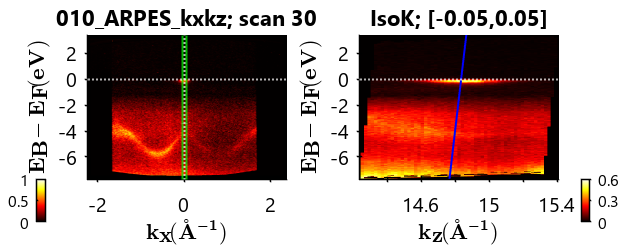

sliceStr_02 = struct with fields:
    isoslice_args: {[30]  ["IsoK"]  [-0.0500 0.0500]  [1]}
         ScanAxis: [760 762 764 766 768 770 772 774 776 778 780 782 784 786 788 790 792 794 796 798 800 802 804 806 808 810 812 814 816 818 820 822 824 826 828 830 832 834 836 838 840 842 844 846 848 850 852 854 856 858 860 862 864 866 868 870 872 … ]
           xField: "kx"
         FileName: '010_ARPES_kxkz'
             Type: "Eb(kx,kz)"
          IsoType: "IsoK"
           IsoWin: [-0.0500 0.0500]
           IsoVal: 0
           IsoRan: 0.0500
           IsoNum: 1
           XSlice: [14.2339 14.2535 14.2731 14.2927 14.3123 14.3319 14.3515 14.3711 14.3907 14.4103 14.4299 14.4495 14.4691 14.4887 14.5083 14.5279 14.5475 14.5671 14.5867 14.6063 14.6259 14.6455 14.6651 14.6847 14.7043 14.7239 14.7435 14.7631 … ]
           YSlice: [688×1 double]
           DSlice: [688×61 double]


% -- EXTRACT ISOK SLICE
sliceType       = "IsoK";           % "IsoE" or "IsoK"
sliceWin        = [-0.05, 0.05];    % Window for the slice to be taken
remap           = 1;                % Remap the slice onto a square grid? 1 or 0
isoslice_args   = {nFrame, sliceType, sliceWin, remap};
plot_result     = 1;                % Show a plot of the data that is extracted. if 1, it will make the plot, if 0 it won't.
[sliceStr_02, ~] = extract_isoSlice(arpes_dat, isoslice_args, plot_result); sliceStr_02

- Data slice formation
- Re-mapping


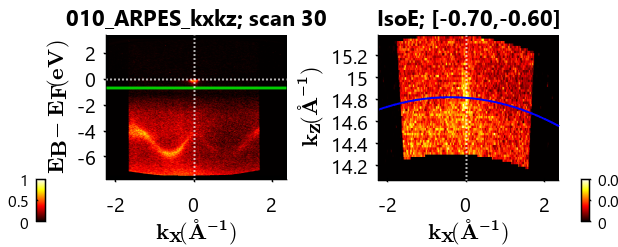

- Data slice formation
- Re-mapping


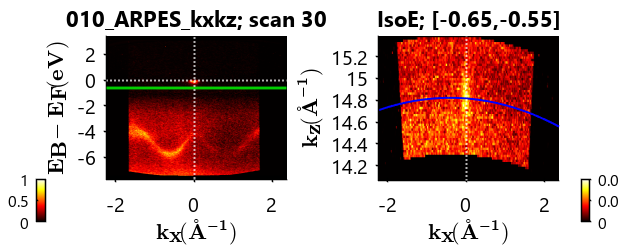

- Data slice formation
- Re-mapping


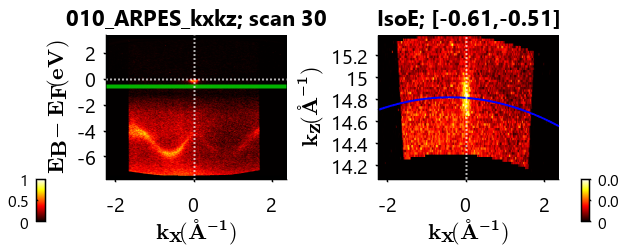

- Data slice formation
- Re-mapping


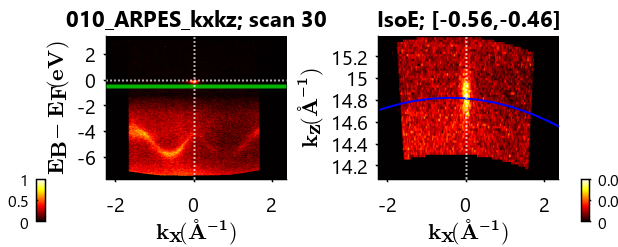

- Data slice formation
- Re-mapping


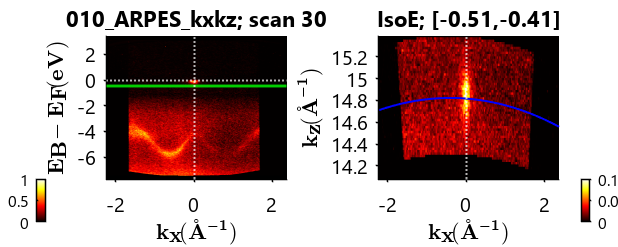

- Data slice formation
- Re-mapping


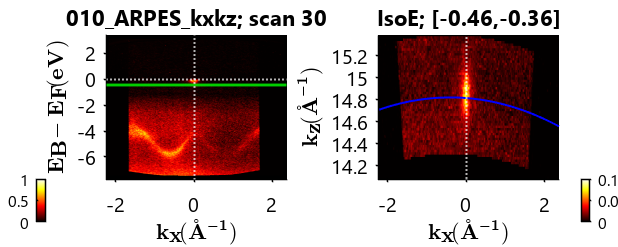

- Data slice formation
- Re-mapping


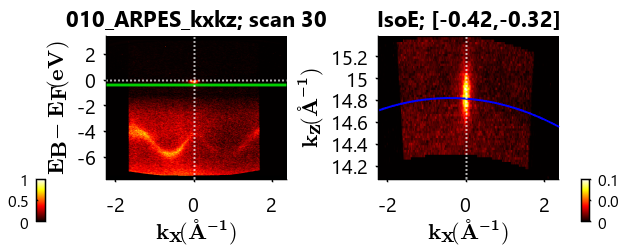

- Data slice formation
- Re-mapping


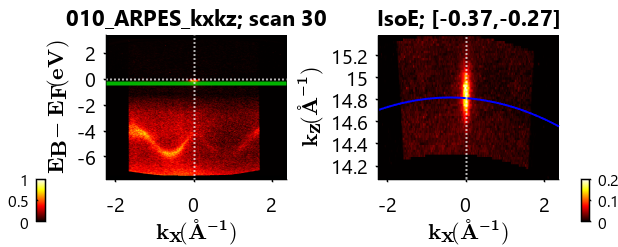

- Data slice formation
- Re-mapping


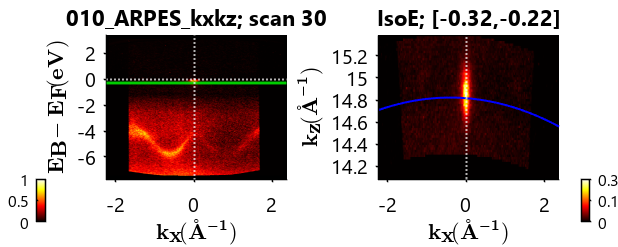

- Data slice formation
- Re-mapping


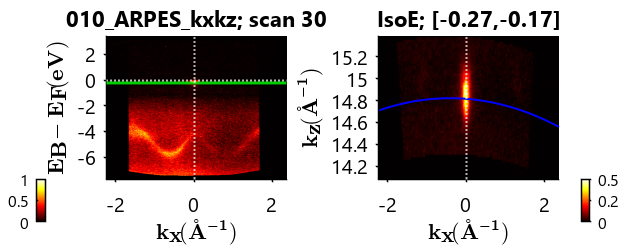

- Data slice formation
- Re-mapping


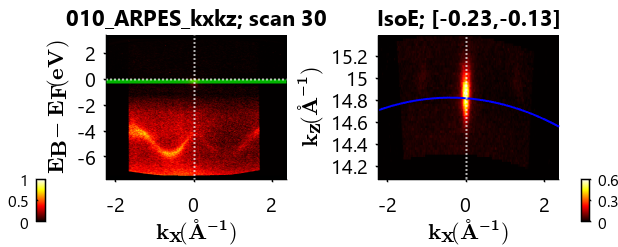

- Data slice formation
- Re-mapping


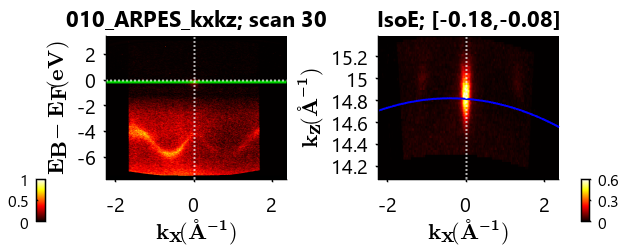

- Data slice formation
- Re-mapping


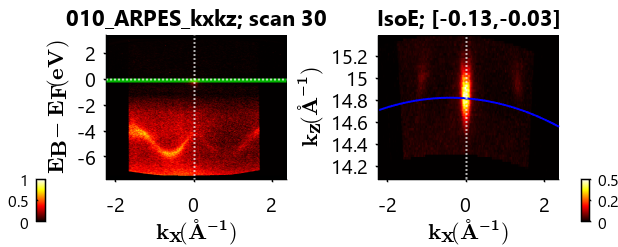

- Data slice formation
- Re-mapping


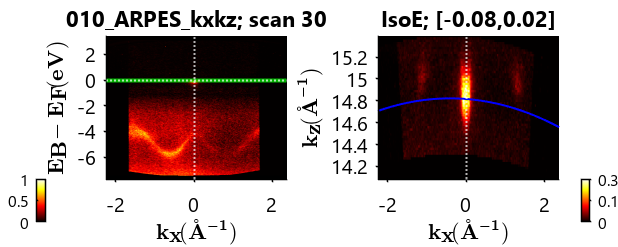

- Data slice formation
- Re-mapping


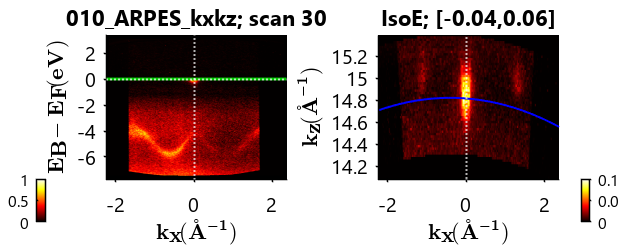

- Data slice formation
- Re-mapping


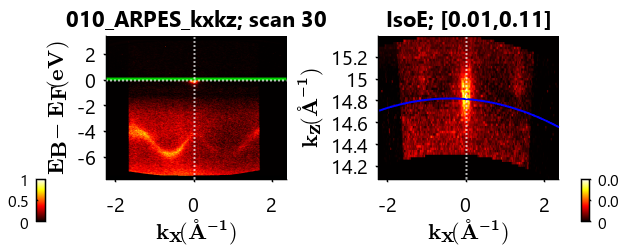

- Data slice formation
- Re-mapping


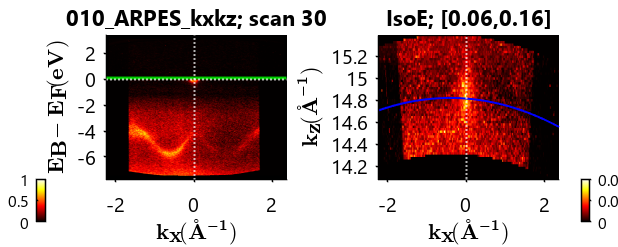

- Data slice formation
- Re-mapping


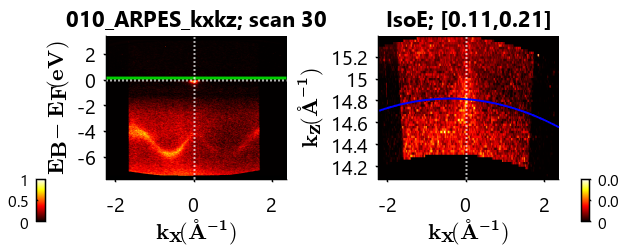

- Data slice formation
- Re-mapping


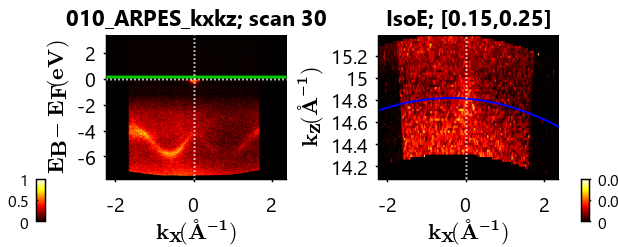

- Data slice formation
- Re-mapping


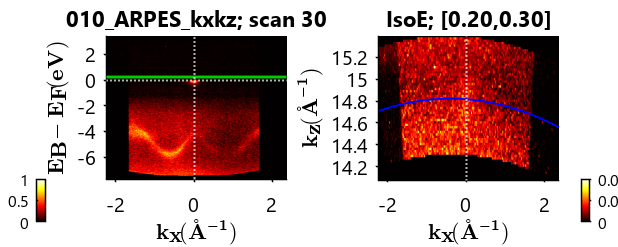

sliceStr_03 = struct with fields:
    isoslice_args: {[30]  ["IsoE"]  [0.0500]  [-0.6500 0.2500]  [20]  [1]}
           xField: "kx"
         FileName: '010_ARPES_kxkz'
             Type: "Eb(kx,kz)"
          IsoType: "IsoE"
           IsoVal: [-0.6500 -0.6026 -0.5553 -0.5079 -0.4605 -0.4132 -0.3658 -0.3184 -0.2711 -0.2237 -0.1763 -0.1289 -0.0816 -0.0342 0.0132 0.0605 0.1079 0.1553 0.2026 0.2500]
           IsoRan: 0.0500
           IsoNum: 20
           IsoWin: [0.2000 0.3000]
           XSlice: {1×20 cell}
           YSlice: {1×20 cell}
           DSlice: {1×20 cell}


% -- EXTRACT SERIES OF ISOE SLICES
isoType          = "IsoE";              % Type of slice to make: "IsoE" (horizontal) or "IsoK" (vertical)
isoWin           = 0.05;                % single, constant value of the integration window.
isoLims          = 0 + [-0.65, 0.25];   % 1x2 vector which gives the window limits of the series [min, max]
isoN             = 20;                  % single, constant value that determines the total number of slices to extract
remap            = 1;                   % Remap the slice onto a square grid? 1 or 0
iso_args         = {nFrame, isoType, isoWin, isoLims, isoN, remap};
plot_result     = 1;                    % Show a plot of the data that is extracted. if 1, it will make the plot, if 0 it won't.
[sliceStr_03, ~] = extract_isoSlice_series(arpes_dat, iso_args, plot_result); sliceStr_03

## (4D) Extracting and plotting an ARPES data-cube

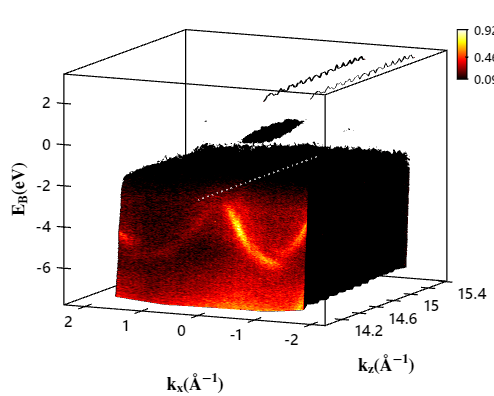

cLimMin         = 0.10;         % minimum threshold, below which the data points are transparent
smoothVal       = 5;            % FWHM of a Gaussian smoothing operation on the 3D cube
isocube_args    = {cLimMin, smoothVal};
[cubeStr, ~]    = extract_isoCube(arpes_dat,  isocube_args);

## (4E) Plotting a series of subplots for all the scans in the ARPES data

-> view series of all scans...


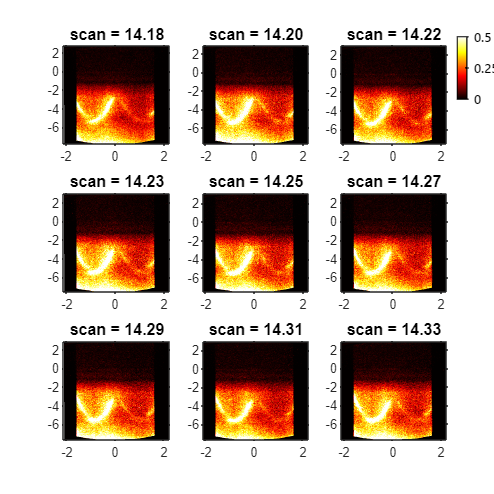

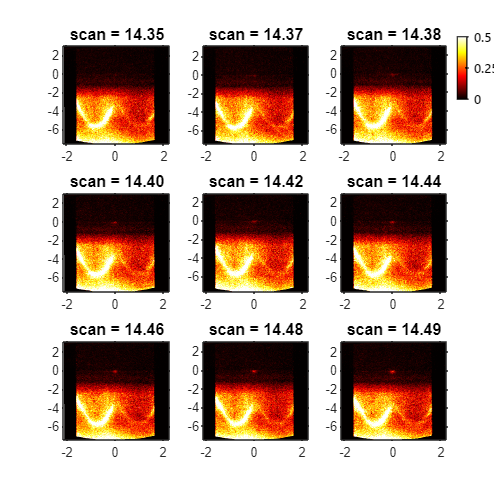

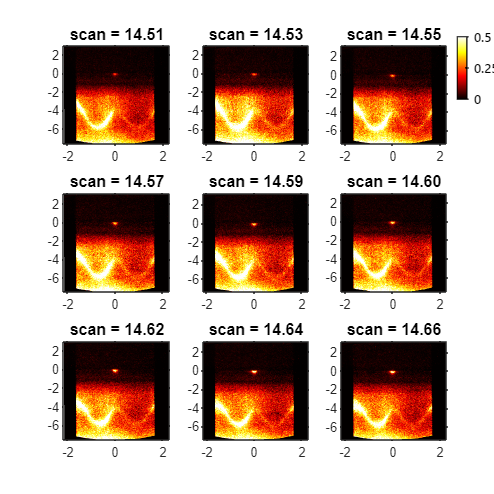

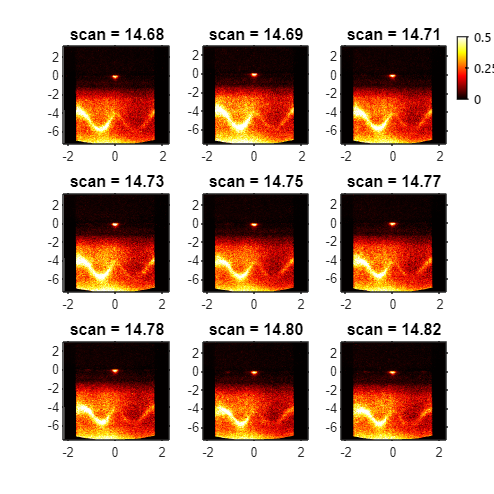

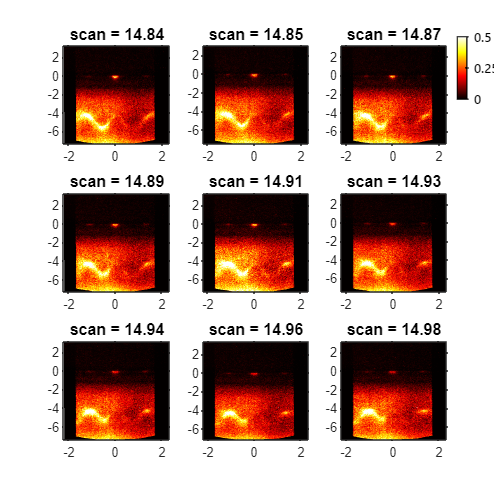

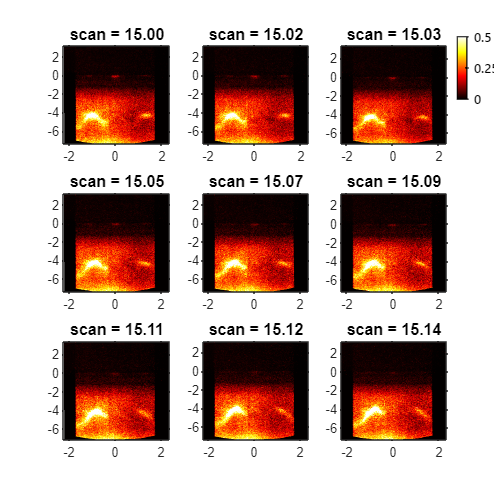

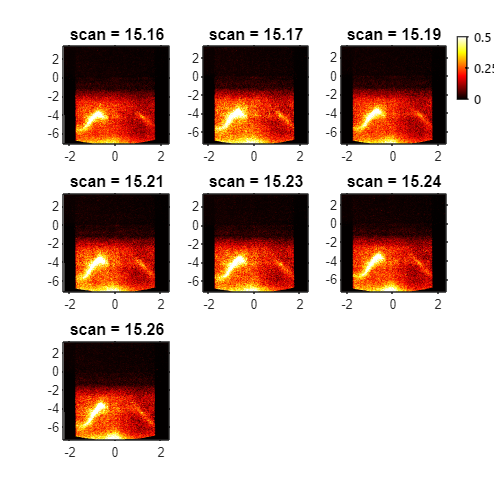

caxLims         = [0, 0.50];       % 1x2 vector in normalised units of the colorscale of each image. 
view_arpes_data_series(arpes_dat, caxLims);

## (4F) Plot and save an image series with a zoom in around a ROI

zLims           = [];
xLims           = [-1, 1];
yLims           = [-4, 1.5];
interpolate     = 0;
ROI             = 1;
xLimsROI        = [-0.35, 0.35];
yLimsROI        = [-0.75, 0.15];
viewVideo_args  = {zLims, xLims, yLims, interpolate, ROI, xLimsROI, yLimsROI};
% save_image_series(arpes_dat, viewVideo_args);